# Data exploration for raw xy files

## PURPOSE

This is code is to calculate general metrics for the xy output from antrax that were merged

## INPUT

antTable = 8×1 table
    Colour
    ______

     "BB" 
     "BG" 
     "BR" 
     "GG" 
     "GR" 
     "RB" 
     "RG" 
     "GG" 


outputFiltered = 4×7 table
       Filename       Treatment    Number    NumAnts     AntOutput     AssignmentRate    InNestRatio
    ______________    _________    ______    _______    ___________    ______________    ___________

    {'xy_C_2.mat'}      {'C'}        2          8       {8×3 table}       0.75175          0.64618  
    {'xy_C_9.mat'}      {'C'}        9          8       {8×3 table}       0.91095           0.3426  
    {'xy_T_1.mat'}      {'T'}        1          8       {8×3 table}       0.90338          0.77867  
    {'xy_T_6.mat'}      {'T'}        6          8       {8×3 table}       0.76118           0.6697  


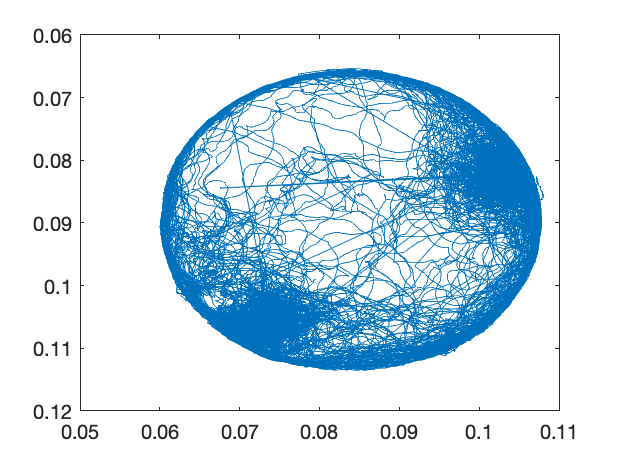

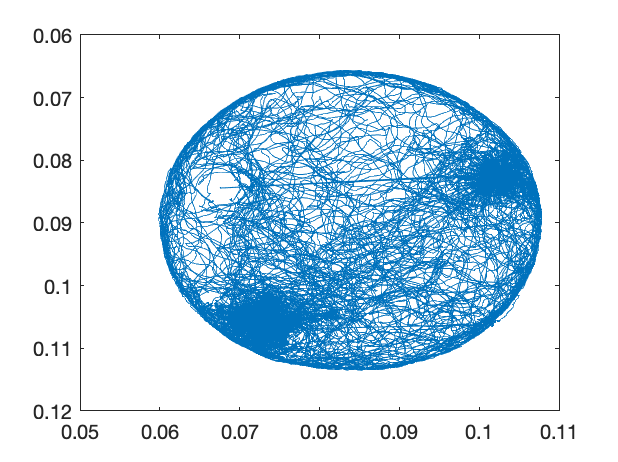

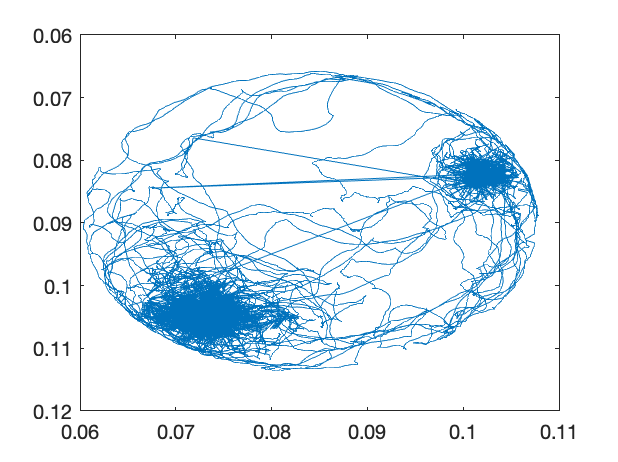

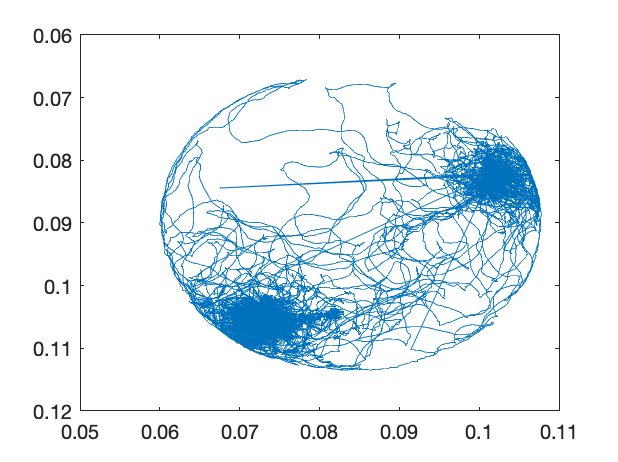

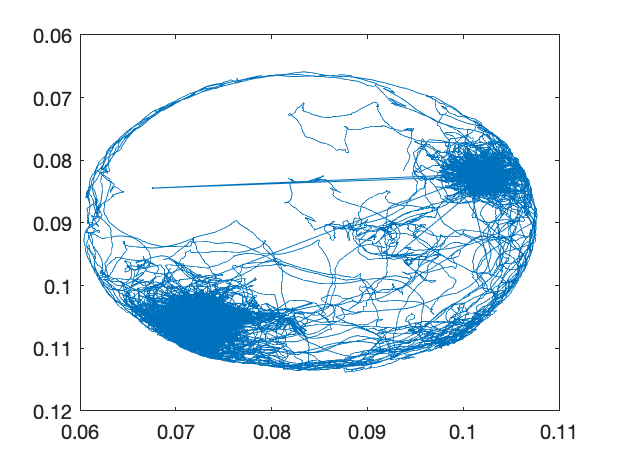

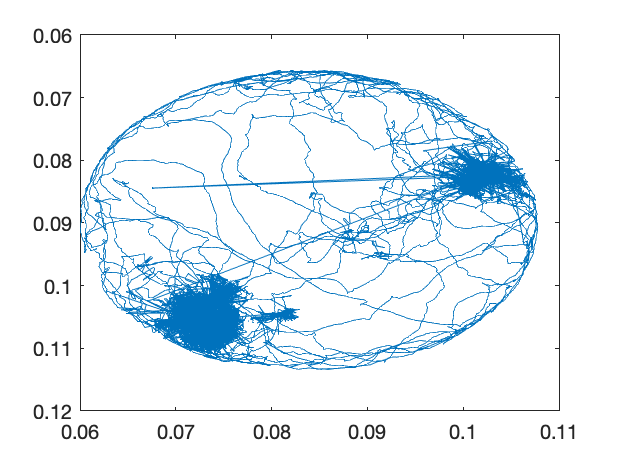

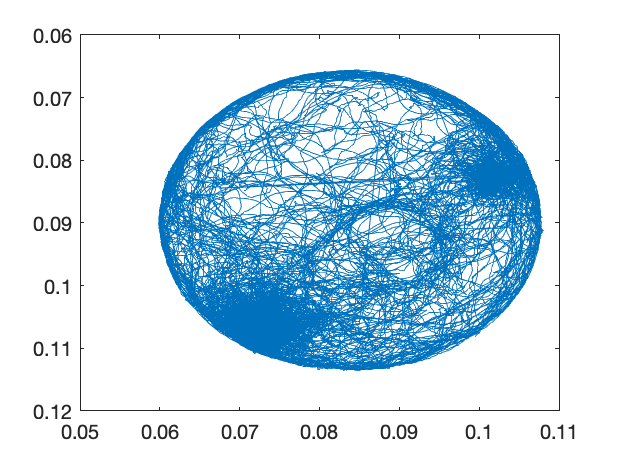

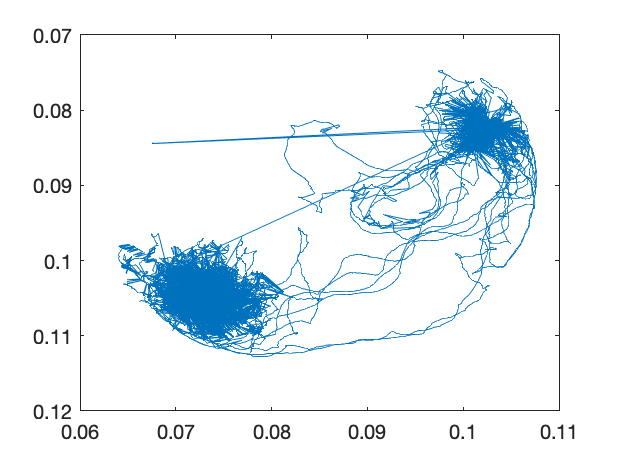

% input file information
xyDir = "/Users/zli/Insync/zimai.li@evobio.eu/Google Drive/DoctorToBe/01_Projects/ZIM01_Nematode/P2_Tracking/01_Data/cam5";

xyFileinfo = dir(fullfile(xyDir,'xy*.mat'));
xyFilename = (sort({xyFileinfo.name}))';

% create output matrix with experiment information in the xy file names
output = table(xyFilename,'VariableNames',{'Filename'});
splitNames = split(output.Filename, ["_","."]);
output.Treatment = splitNames(:, 2);
output.Number = str2double(splitNames(:, 3));

% data filtering
treatRm = "X"; % treatment to remove
frameKeep = 864000; % frame to keep

% ant information
antColour = ["BB","BG","BR","GG","GR","RB","RG","GG"]';
antTable = table(antColour, 'VariableNames',{'Colour'}) 


## Clean Data

% filter some treatments
outputFiltered = output(output.Treatment~=treatRm,:);
inNestWithNans = copyNans(xy, inNest);

## Calculate Metrics for Ants and Colonies

**ATTENTION: **Run FindNest Before this section

% create empty matrix 
numFile = length(outputFiltered.Filename);
xyMatrix = {};

for i = 1:numFile
    xyMatrix = load(fullfile(xyDir, outputFiltered.Filename(i))).xy(1:frameKeep,:); % load xy matrix
    numAnts = size(xyMatrix, 2)/2; % number of ants equals to number of columns
    

    %% calculate basic statistics for ants
    for j = 1:length(antColour)
        antXy = xyMatrix(:,[j*2-1, j*2]);
        assignmentRate = 1 - sum(isnan(antXy),'all')/(size(xyMatrix, 1)*2);
        antTable.AssignmentRate(j) = assignmentRate;
        antTable.InNestRatio(j) = sum(inNestWithNans{i,1}(:,j),"omitnan")/length(inNestWithNans{i,1}(:,j));  
        % ALERT: Please make sure to run FindNest before!!!
    end
    
    %% calculate basic statistics for colonies  
   outputFiltered.NumAnts(i) = numAnts; % count number of ants
   outputFiltered.AntOutput{i} = antTable ; % insert ant output
   outputFiltered.AssignmentRate(i) = mean(outputFiltered.AntOutput{i,1}.AssignmentRate); % count mean assignment rate
   outputFiltered.InNestRatioMean(i) = mean(outputFiltered.AntOutput{i,1}.InNestRatio); % count mean in-nest ratio
   outputFiltered.InNestRatioGlobal(i) = sum(inNestWithNans{i,1}, "all", "omitnan")/(length(inNestWithNans{i,1})*numAnts);
end

outputFiltered
